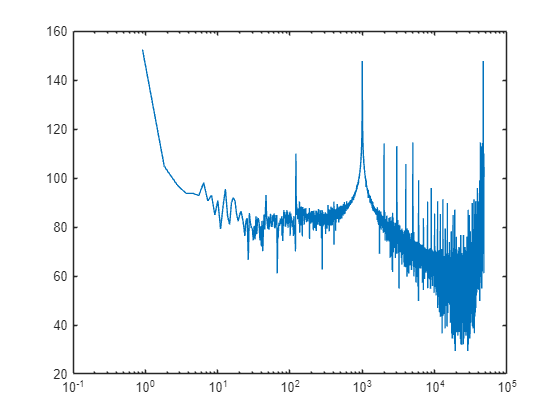

raw = readtable("C:\Users\mpolj\AppData\Local\teraterm5\teraterm.log");
doub = table2array(raw);
bin_d = dec2bin(doub);
tt = size(bin_d);
bin_data = bin_d(:, tt(2)-15-16:tt(2)-16);
doub_data = typecast(uint16(bin2dec(bin_data)), 'int16');
doub_data(abs(doub_data)>5000000) = 0;  % change value to 500 if spikes are seen

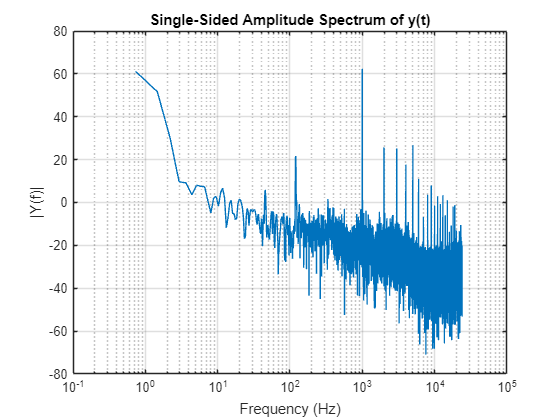

% used for MiniZed testing
%fft_plot(double(doub_data), 2500000/8/2/2/2, 'log', 'dB', @blackman);
% used for ZedBoard testing

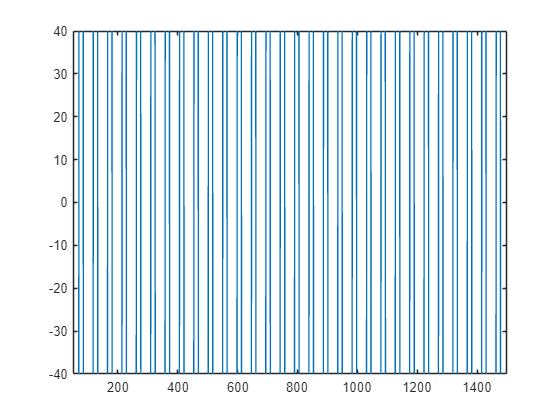

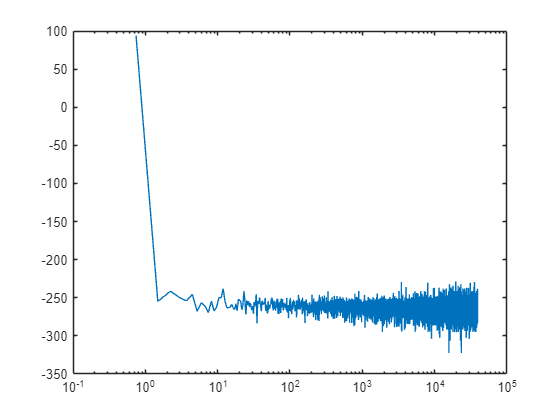

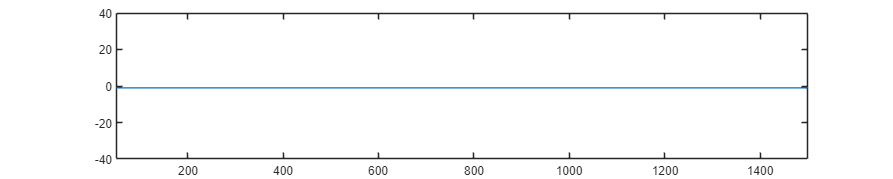

fft_plot(double(doub_data), 3072000/8/2/2/2, 'log', 'dB', @blackman);
fig = figure();
fig.Position(3:4) = [1000, 200];
bu = 1:length(doub_data);
plot(bu, doub_data)
xlim([50 1500])
ylim([-40 40])

%remove dc offset and funny spikes
NUMS = [1, -1, 0.996]

NUMS =     1.0000   -1.0000    0.9960


F_len = 9;
FUL_len = 16;
fixed_NUMS = sfi(NUMS, FUL_len+F_len, F_len)

fixed_NUMS =     1.0000   -1.0000    0.9961

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 25
        FractionLength: 9

bin_fixed_NUMS = bin(fixed_NUMS)

bin_fixed_NUMS = '0000000000000001000000000   1111111111111111000000000   0000000000000000111111110'

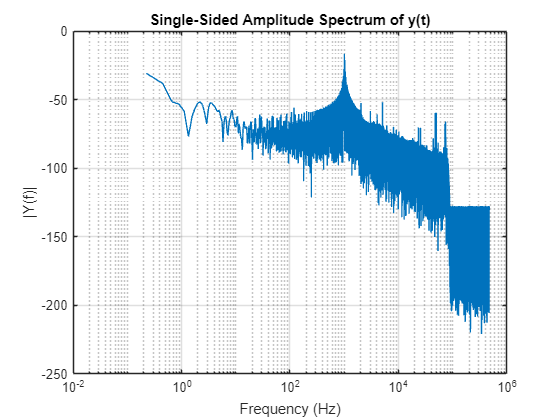

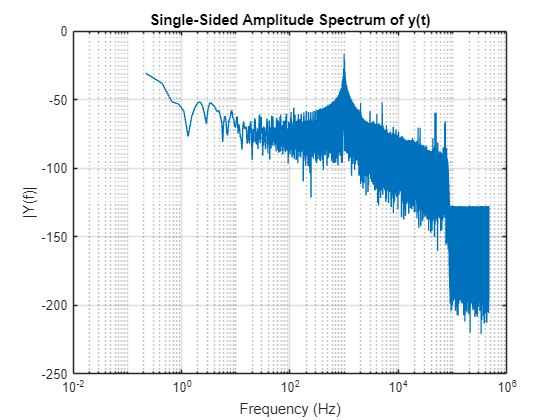

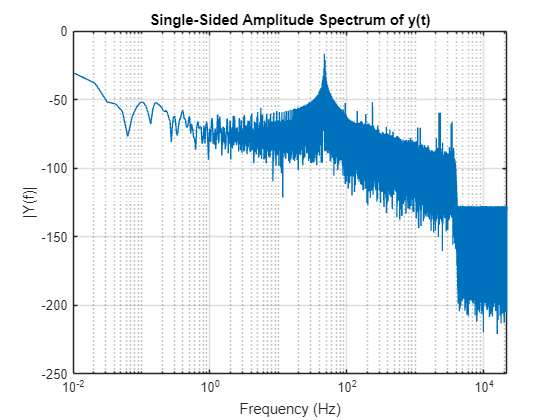

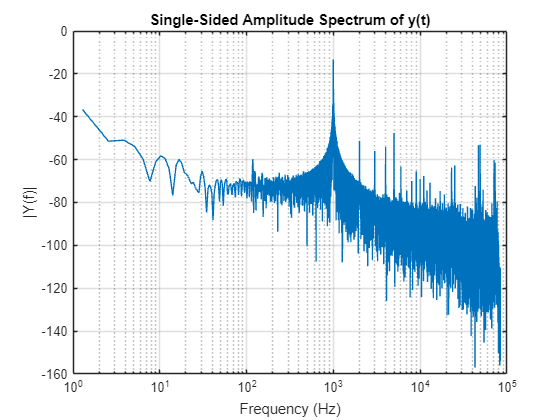

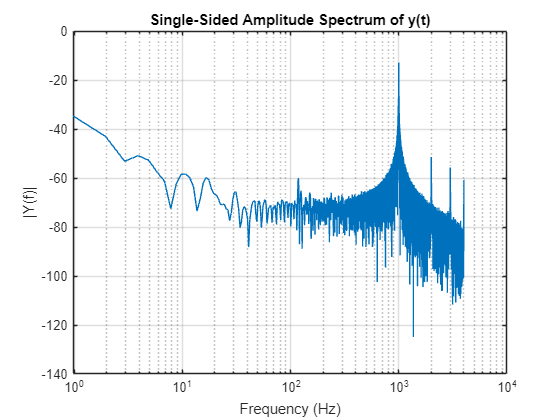

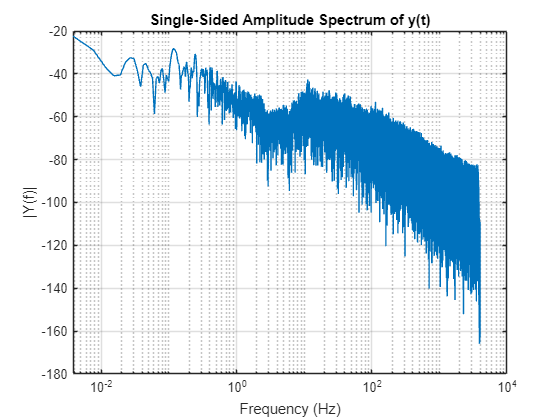

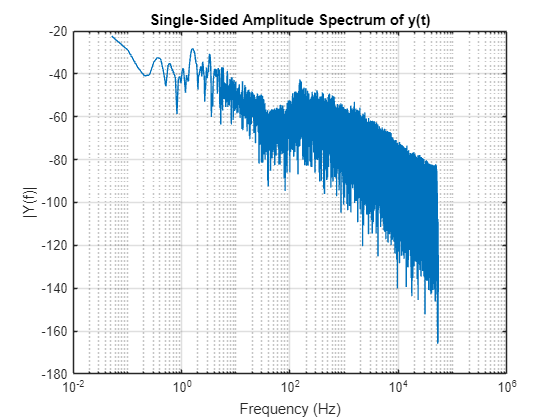


audiowrite(['ZedBoard_uart_ic_.wav'], rescale(double(doub_data), -1, 0.99), 2000000/8/2/2/2)


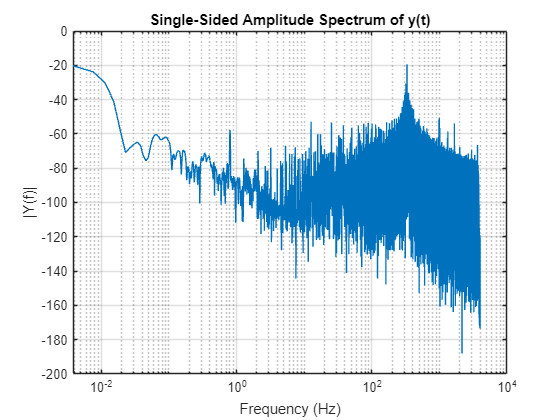

% usb IC testing and resampling
[zedboard_usb_raw_ic,fs_usb] = audioread("zedboard_usb_raw_ic.wav");
fft_plot(zedboard_usb_raw_ic, fs_usb, 'log', 'dB', @blackman);

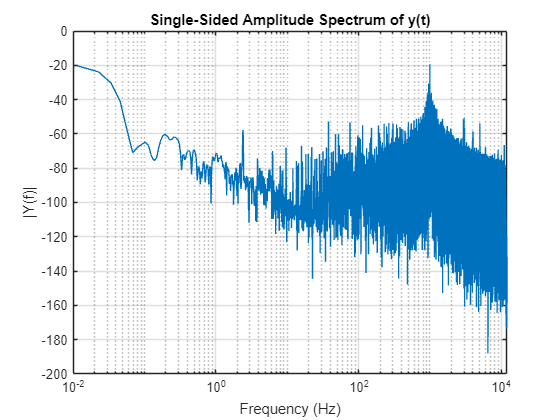

audiowrite("zedboard_usb_res_ic.wav", zedboard_usb_raw_ic, 48000/2);
[zedboard_usb_res_ic,fs_usb_res] = audioread("zedboard_usb_res_ic.wav");
fft_plot(zedboard_usb_res_ic, fs_usb_res, 'log', 'dB', @blackman);

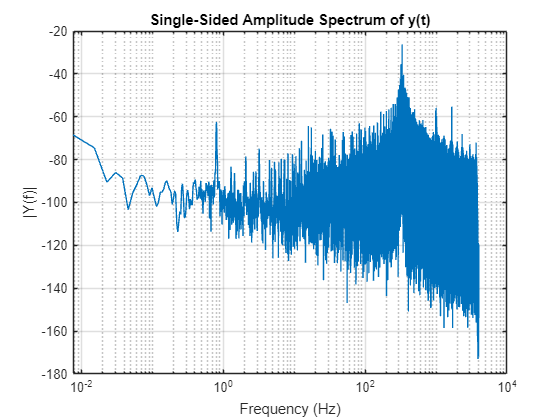

% usb FIR decimation testing and resampling
[zedboard_usb_raw_fir,fs_usb_fir] = audioread("zedboard_usb_raw_fir.wav");
fft_plot(zedboard_usb_raw_fir, fs_usb_fir, 'log', 'dB', @blackman);

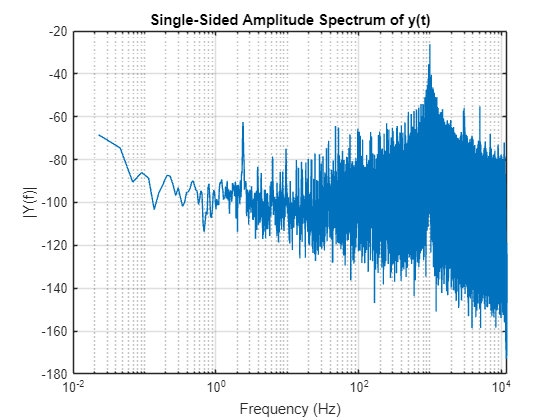

audiowrite("zedboard_usb_res_fir.wav", zedboard_usb_raw_fir, 48000/2);
[zedboard_usb_res_fir,fs_usb_fir_res] = audioread("zedboard_usb_res_fir.wav");
fft_plot(zedboard_usb_res_fir, fs_usb_fir_res, 'log', 'dB', @blackman);

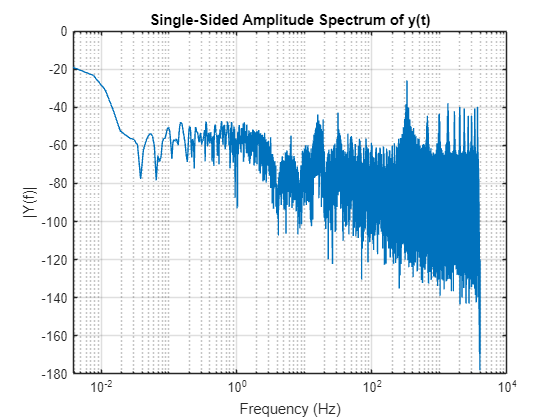

% usb halfband decimation testing and resampling
[zedboard_usb_raw_hbf,fs_usb_hbf] = audioread("zedboard_usb_raw_hbf.wav");
fft_plot(zedboard_usb_raw_hbf, fs_usb_hbf, 'log', 'dB', @blackman);

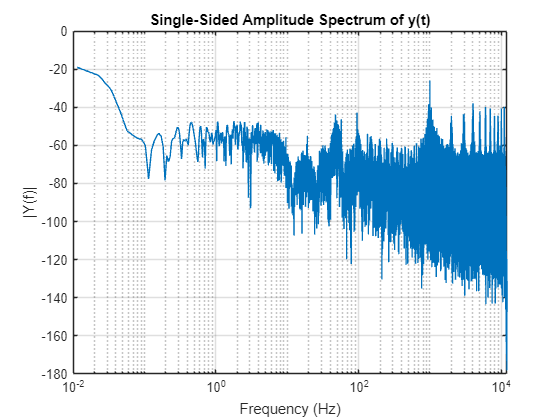

audiowrite("zedboard_usb_res_hbf.wav", zedboard_usb_raw_hbf, 48000/2);
[zedboard_usb_res_hbf,fs_usb_hbf_res] = audioread("zedboard_usb_res_hbf.wav");
fft_plot(zedboard_usb_res_hbf, fs_usb_hbf_res, 'log', 'dB', @blackman);

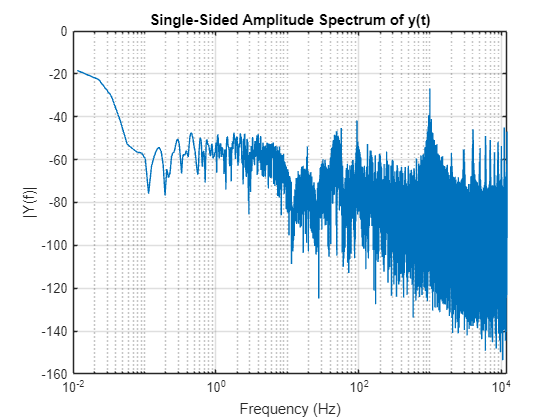

zedboard_usb_res_hbf(abs(zedboard_usb_res_hbf)>0.3) = 0;
fft_plot(zedboard_usb_res_hbf, fs_usb_hbf_res, 'log', 'dB', @blackman);

audiowrite("zedboard_usb_res_hbf_fixed.wav", zedboard_usb_res_hbf, 48000/2);

% test direcion calculation
x_dir = [32,1,45,15,1,26,5,38,17,1,27,5,42,17,0,25,1,40,11,0,23,40,15,0,22,3,36,8,0,22];
y_dir = [33,35,43,36,3,40,21,48,23,0,33,21,40,23,0,43,30,46,31,0,35,46,26,0,35,13,45,31,0,35];

x_loc = mean(x_dir)

x_loc = 17.2667

y_loc = mean(y_dir)

y_loc = 27.1667